# Lab 4

clear;
warning("off");

## Experiment 1

Ut = 0.025;
load("exp1_1_new.mat")

voltage1 = Diode_Voltage;
current1 = ch1;
[Is1, VT1, k1] = ekvfit(voltage1, current1, 0.0005);

load("exp1_2_new.mat")

voltage2 = Diode_Voltage;
current2 = ch1;
[Is2, VT2, k2] = ekvfit(voltage2, current2, 0.0005);

load("exp1_3_new.mat")

voltage3 = Diode_Voltage;
current3 = ch1;
[Is3, VT3, k3] = ekvfit(voltage3, current3, 0.0005);
load("exp1_4_new.mat")

voltage4 = Diode_Voltage;
current4 = ch1;
[Is4, VT4, k4] = ekvfit(voltage4, current4, 0.0005);
clf
figure(1)

[Is, VT, k] = ekvfit(voltage3, current3, 0.0005);
compute_current = @(voltage) Is .* log(1 + exp((k*(voltage-VT))/(2*Ut))).^2;
theoretical_current1 = compute_current(voltage3);
transistors = ["First Transistor";"Second Transistor";"Third Transistor"; "Fourth Transistor"];
k_vals = [k1; k2; k3; k4];
VT_vals = [VT1; VT2; VT3; VT4];
Is_vals = [Is1; Is2; Is3; Is4];
Diode_Values = table(transistors, k_vals, VT_vals, Is_vals, 'VariableNames', ["Transistors", " Reciprocal Subthreshold Slope Factor", "Zero-Bias Threshold Voltage (Volts)","Specific current (Amps)"])

Diode_Values = 4×4 table
        Transistors         Reciprocal Subthreshold Slope Factor    Zero-Bias Threshold Voltage (Volts)    Specific current (Amps)
    ___________________    _____________________________________    ___________________________________    _______________________
    "First Transistor"                    0.74087                                 0.57532                        1.5991e-06       
    "Second Transistor"                   0.76822                                 0.57192                        1.4648e-06       
    "Third Transistor"                    0.74156                                 0.57502                        1.5709e-06       
    "Fourth Transistor"                   0.70816                                 0.57713                        1.7346e-06       

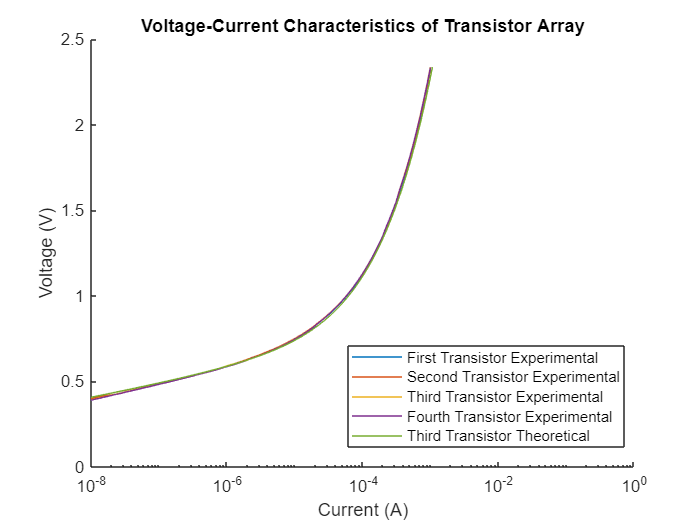

hold on 
title("Voltage-Current Characteristics of Transistor Array")
ylabel("Voltage (V)")
xlabel("Current (A)")
plot(current1,voltage1, 'DisplayName',"First Transistor Experimental")
plot(current2,voltage2, 'DisplayName',"Second Transistor Experimental")
plot(current3,voltage3, 'DisplayName',"Third Transistor Experimental")
plot(current4,voltage4, 'DisplayName',"Fourth Transistor Experimental")
plot(theoretical_current1, voltage3, 'DisplayName',"Third Transistor Theoretical")
set(gca, "XScale", "log");
xlim([10^-8, 1])
legend('show', 'Location', 'best');
hold off

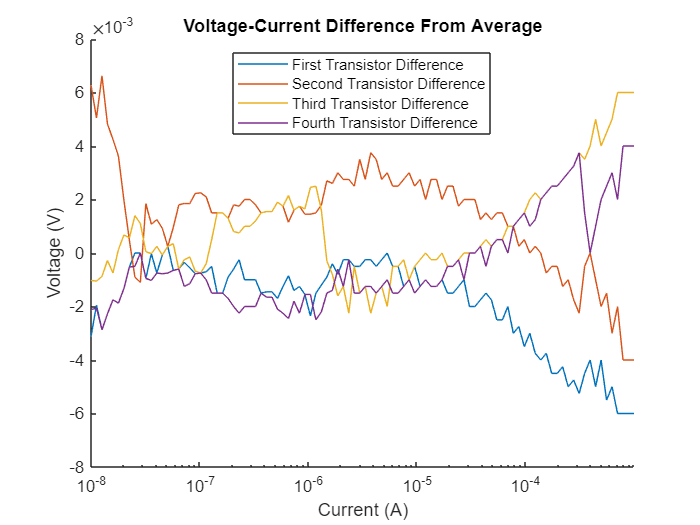

mean = (flip(voltage1) + flip(voltage2) + flip(voltage3) + flip(voltage4))/4;

clf;
figure(2)
hold on
title("Voltage-Current Difference From Average")
ylabel("Voltage (V)")
xlabel("Current (A)")
plot(flip(current1), flip(voltage1) - mean, 'DisplayName',"First Transistor Difference")
plot(flip(current2), flip(voltage2) - mean, 'DisplayName',"Second Transistor Difference")
plot(flip(current3), flip(voltage3) - mean, 'DisplayName',"Third Transistor Difference")
plot(flip(current4), flip(voltage4) - mean, 'DisplayName',"Fourth Transistor Difference")
set(gca, "XScale", "log");
legend('show', 'Location', 'best');
hold off

The voltage current characteristic matches very well across weak, moderate and strong inversion as they do not deviate more than 7 milliovolts from the average. However, the most variation from the average is seen during strong inversion, meaning that is when they match the worst, They match relatively well during weak and moderate inversion. 

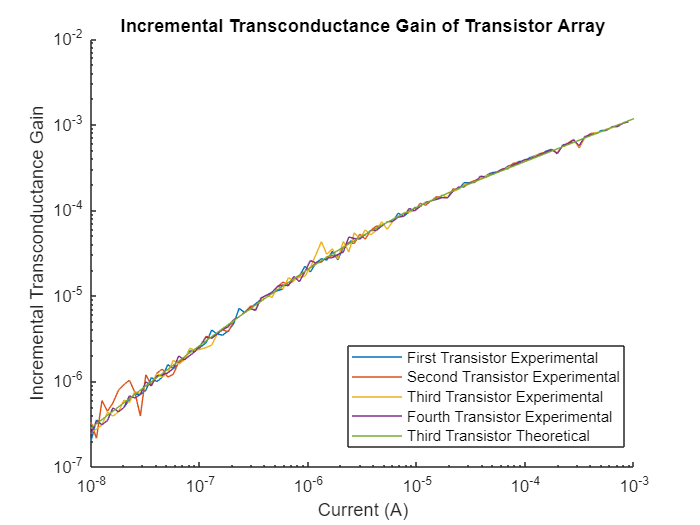

compute_gm = @(current, Is, k) k.*(sqrt(Is .* current)./Ut) .* (1-exp(-sqrt(current./Is)));

exp1_gm = diff(current1)./diff(voltage1);
exp2_gm = diff(current2)./diff(voltage2);
exp3_gm = diff(current3)./diff(voltage3);
exp4_gm = diff(current4)./diff(voltage4);

theo3_gm = compute_gm(current3, Is , k);
clf;
figure(7);
hold on
title("Incremental Transconductance Gain of Transistor Array")
ylabel("Incremental Transconductance Gain")
xlabel("Current (A)")
plot(current1(2:end), exp1_gm, 'DisplayName',"First Transistor Experimental")
plot(current2(2:end), exp2_gm, 'DisplayName',"Second Transistor Experimental")
plot(current3(2:end), exp3_gm, 'DisplayName',"Third Transistor Experimental")
plot(current4(2:end), exp4_gm, 'DisplayName',"Fourth Transistor Experimental")
plot(current3, theo3_gm, 'DisplayName',"Third Transistor Theoretical");
legend('show', 'Location', 'best');
set(gca, "XScale", "log");
set(gca, "YScale", "log");
hold off

The theoretical fit matches very well with the experimental data.

## Experiment 2

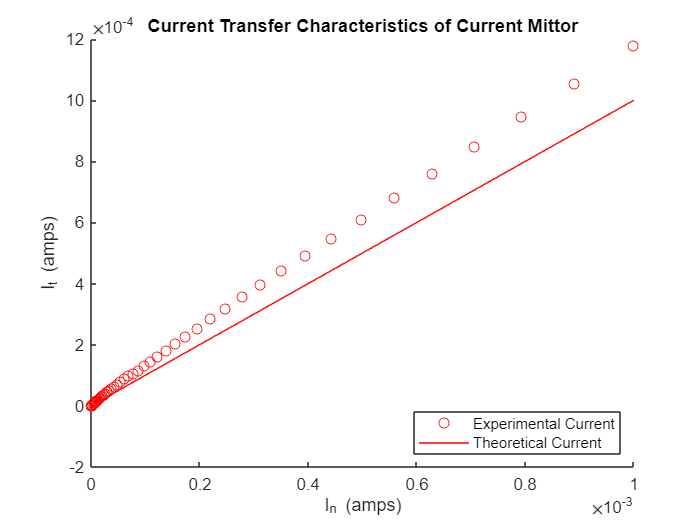

clear;
clf;
load("Ex_2_1.mat");
theo_fit = ch1;
figure(3);
hold on
loglog(ch1, MDiode_Current, 'ro');
loglog(ch1, theo_fit, 'r-');
title("Current Transfer Characteristics of Current Mirror");
xlabel("I_i_n (amps)");
ylabel("I_o_u_t (amps)")
legend("Experimental Current", "Theoretical Current", "location", "southeast");
hold off

In a current mirror, the circuit is designed to essentially copy a current from an active device. From the graph, the current matches relatively well, which means that it is wel within the expected behaviour of a current mirror. However, as we get to higher and higher currents we see a lot more deviation in the experimental data from the mirror behaviour we expect to see. 

## Experiment 3

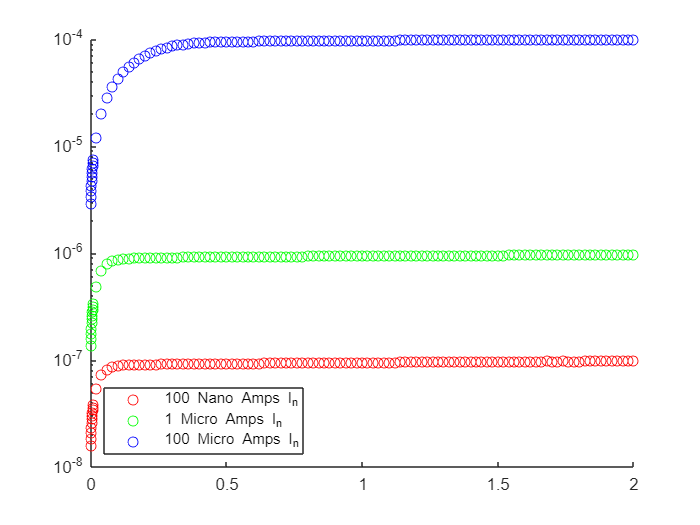

clear;
clf;
load("Ex_3_100nano.mat");
nano_100_voltage = ch2_voltage;
nano_100_current = mos_current;
load("Ex_3_1micro.mat");
micro_1_voltage = ch2_voltage;
micro_1_current = mos_current;
load("Ex_3_100micro.mat")
micro_100_voltage = ch2_voltage;
micro_100_current = mos_current;

figure();
hold on
plot(nano_100_voltage, nano_100_current, 'ro');
plot(micro_1_voltage, micro_1_current, 'go');
plot(micro_100_voltage, micro_100_current, 'bo');
set(gca, "YScale", "log");
xlim([0 2])
legend("100 Nano Amps I_i_n", "1 Micro Amps I_i_n", "100 Micro Amps I_i_n", "location", "southwest")
hold off

I_in_Current = ["100 Nano Amps";"1 Micro Amps";"100 Micro Amps"];
I_in = [1e-7; 1e-6; 1e-4];
Early_Voltage = [26.32; 30.855; 29.938];
Saturation_Current = [9.16e-8; 9.14e-7; 9.16e-5];
Early_Effect_Resistance = Early_Voltage./Saturation_Current;
Transistor_On_Resistance = 1./Early_Effect_Resistance;
Intrinsic_Gain = Early_Effect_Resistance./Transistor_On_Resistance;
MOS_properties = table(I_in_Current, Early_Voltage, Saturation_Current, Early_Effect_Resistance, Transistor_On_Resistance, Intrinsic_Gain, 'VariableNames', ["I_in Current (Amps)", "Early Voltage (Volts)", "Saturation Current (Amps)","Early Effect Resistance (Ohms)","Transistor On Resistance (Ohms)","Intrinsic Gain"])

MOS_properties = 3×6 table
    I_in Current (Amps)    Early Voltage (Volts)    Saturation Current (Amps)    Early Effect Resistance (Ohms)    Transistor On Resistance (Ohms)    Intrinsic Gain
    ___________________    _____________________    _________________________    ______________________________    _______________________________    ______________
     "100 Nano Amps"               26.32                    9.16e-08                       2.8734e+08                        3.4802e-09                 8.2562e+16  
     "1 Micro Amps"               30.855                    9.14e-07                       3.3758e+07                        2.9622e-08                 1.1396e+15  
     "100 Micro Amps"             29.938                    9.16e-05                       3.2683e+05        

100 Nano Amps:

    Early Voltage - 26.35 Volts

1 Micro Amp:

    Early Voltage - 29.58 Volts

100 Micro Amps:

    Early Voltage - 33.75 Volts

The approximations based on the assumptions that the intrinsic gain is greater than unity is a good one because the intrinsic gain is significantly greater than 1 in all 3 types of inversion. Across inversion levels, this assumption is generally a good one.